%% Skin Cancer Detection with SVM + Simple Oversampling + Styled Confusion Matrix
close all; clear; clc;
disp('🔬 Welcome to the Skin Cancer Detection System!');

🔬 Welcome to the Skin Cancer Detection System!



%% Step 1: Load Ground Truth & Images
[excelFile, excelPath] = uigetfile({'*.xlsx;*.csv'}, 'Select the Ground Truth File');
if isequal(excelFile, 0), error('No ground truth file selected.'); end
fullExcelPath = fullfile(excelPath, excelFile);

imageFolder = uigetdir('', 'Select Folder with Images');
if isempty(imageFolder), error('Image folder not selected correctly.'); end

metadata = readtable(fullExcelPath);
imageFiles = dir(fullfile(imageFolder, '*.jpg'));
disp(['🖼 Images found: ', num2str(length(imageFiles))]);

🖼 Images found: 10015



%% Step 2: Feature Extraction
features = [];
labels = [];
classNames = metadata.Properties.VariableNames(2:end);
numImages = min(height(metadata), length(imageFiles));

for i = 1:numImages
    img = imread(fullfile(imageFiles(i).folder, imageFiles(i).name));
    if size(img, 3) == 3, img = rgb2gray(img); end
    img = imresize(img, [64 64]);
    feat = extractHOGFeatures(img, 'CellSize', [16 16]);
    features = [features; feat];

    row = metadata{i, 2:end};
    labelIdx = find(row == 1);
    labels = [labels; string(classNames{labelIdx})];
end

labels = categorical(cellstr(labels)); % Fixed for compatibility
disp('✅ Feature extraction done.');

✅ Feature extraction done.



%% Step 3: Dataset Balancing with Simple Oversampling
disp('📈 Applying oversampling to balance dataset...');

📈 Applying oversampling to balance dataset...


[featuresBalanced, labelsBalanced] = simpleOversample(features, labels);

% Viva Note:
% We used simple random oversampling (not full SMOTE) to balance the dataset
% by duplicating minority samples to match the largest class.
% This method reduces training time while still improving class balance.

%% Step 4: Train SVM Model
disp('🧠 Training SVM...');

🧠 Training SVM...


cv = cvpartition(size(featuresBalanced, 1), 'HoldOut', 0.2);
trainX = featuresBalanced(training(cv), :);
trainY = labelsBalanced(training(cv));
testX = featuresBalanced(test(cv), :);
testY = labelsBalanced(test(cv));

svmModel = fitcecoc(trainX, trainY);
save('Optimized_SVM_Model.mat', 'svmModel');
disp('✅ Model Trained and Saved.');

✅ Model Trained and Saved.



%% Step 5: Evaluation with Styled Confusion Matrix
disp('📊 Evaluating the model...');

📊 Evaluating the model...


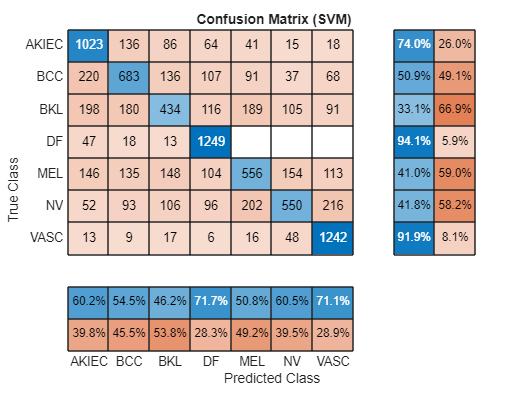

predY = predict(svmModel, testX);
[confMat, order] = confusionmat(testY, predY);

figure;
confMatChart = confusionchart(confMat, order);
confMatChart.Title = ' Confusion Matrix (SVM)';
confMatChart.FontName = 'Arial';
confMatChart.Normalization = 'absolute';
confMatChart.RowSummary = 'row-normalized';
confMatChart.ColumnSummary = 'column-normalized';


% Metric calculations
classes = categories(testY);
numClasses = numel(classes);
precision = zeros(numClasses, 1);
recall = zeros(numClasses, 1);
f1 = zeros(numClasses, 1);

for i = 1:numClasses
    c = classes{i};
    TP = sum((predY == c) & (testY == c));
    FP = sum((predY == c) & (testY ~= c));
    FN = sum((predY ~= c) & (testY == c));

    precision(i) = TP / (TP + FP + eps);
    recall(i) = TP / (TP + FN + eps);
    f1(i) = 2 * (precision(i) * recall(i)) / (precision(i) + recall(i) + eps);
end

acc = mean(predY == testY);
macroPrec = mean(precision);
macroRec = mean(recall);  
macroF1 = mean(f1);

fprintf('\n📈 Accuracy: %.2f%%\n', acc * 100);


📈 Accuracy: 61.12%


fprintf('📌 Macro Precision: %.2f%%\n', macroPrec * 100);

📌 Macro Precision: 59.27%


fprintf('📌 Macro Recall: %.2f%%\n', macroRec * 100);

📌 Macro Recall: 60.97%


fprintf('📌 Macro F1 Score: %.2f%%\n\n', macroF1 * 100);

📌 Macro F1 Score: 59.13%



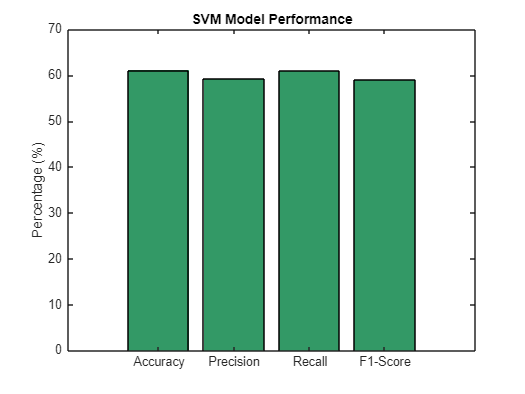


% Bar plot of metrics
figure;
bar([acc macroPrec macroRec macroF1] * 100, 'FaceColor', [0.2 0.6 0.4]);
set(gca, 'XTickLabel', {'Accuracy', 'Precision', 'Recall', 'F1-Score'});
ylabel('Percentage (%)');
title('SVM Model Performance');


%% Step 6: Webcam Prediction
disp('📸 Live Webcam Prediction...');

📸 Live Webcam Prediction...


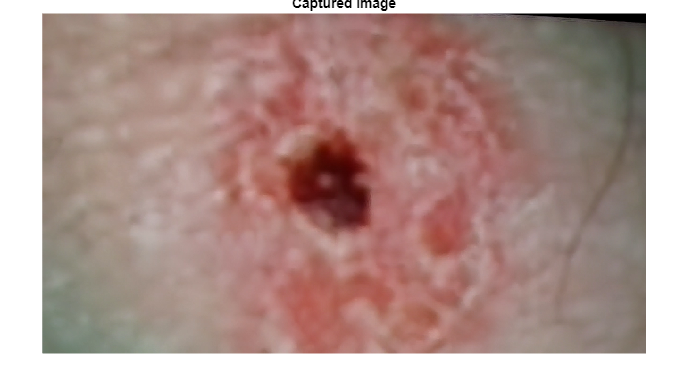

cam = webcam; pause(2);
liveImg = snapshot(cam); clear cam;
imshow(liveImg); title('Captured Image');

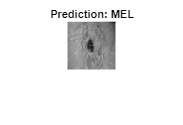


liveImg = imresize(liveImg, [64 64]);
if size(liveImg, 3) == 3, liveImg = rgb2gray(liveImg); end

liveFeat = extractHOGFeatures(liveImg, 'CellSize', [16 16]);
livePred = predict(svmModel, liveFeat(:)');

figure;
imshow(liveImg);
title(['Prediction: ', char(livePred)]);

disp(['🔍 Predicted Class: ', char(livePred)]);

🔍 Predicted Class: MEL



%% Simple Oversampling Function (Renamed from SMOTE)
function [X_res, Y_res] = simpleOversample(X, Y)
    classes = categories(Y);
    counts = countcats(Y);
    maxCount = max(counts);

    X_res = [];
    Y_res = categorical;

    for i = 1:numel(classes)
        class = classes{i};
        idx = (Y == class);
        Xi = X(idx, :);
        ni = sum(idx);

        % Original samples
        X_res = [X_res; Xi];
        Y_res = [Y_res; repmat(categorical({class}), ni, 1)];

        % Duplicate samples for balance
        extra = maxCount - ni;
        if extra > 0
            reps = Xi(randi(ni, extra, 1), :);
            X_res = [X_res; reps];
            Y_res = [Y_res; repmat(categorical({class}), extra, 1)];
        end
    end
end

  